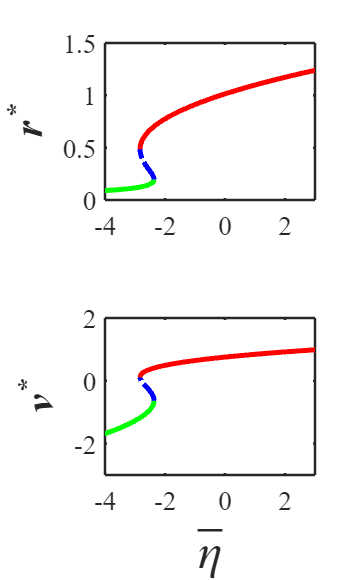

load('COBASaddleResults.mat')

% Set default properties for the current script
set(0, 'DefaultAxesFontName', 'Times New Roman');
set(0, 'DefaultTextFontName', 'Times New Roman');

COBAg = cat(2, flip(COBAg(1:300)), flip(COBAg(301:end)));
COBASaddleR = cat(2, flip(COBASaddleR(1:300)), flip(COBASaddleR(301:end)));
COBASaddleV = cat(2, flip(COBASaddleV(1:300)), flip(COBASaddleV(301:end)));

COBAg1 = COBAg(1:310);
COBAg2 = COBAg(310:322);
COBAg3 = COBAg(322:end);
COBASaddleR1 = COBASaddleR(1:310);
COBASaddleR2 = COBASaddleR(310:322);
COBASaddleR3 = COBASaddleR(322:end);
COBASaddleV1 = COBASaddleV(1:310);
COBASaddleV2 = COBASaddleV(310:322);
COBASaddleV3 = COBASaddleV(322:end);

figure('Units', 'inches', 'Position', [0, 0, 6, 10]); % 7 pulgadas de ancho, 7 pulgadas de alto

% Primer subplot
subplot(2, 1, 1);
plot(COBAg1, COBASaddleR1, '-g', 'LineWidth', 3); % Línea verde sólida para y1
hold on;
plot(COBAg2, COBASaddleR2, '-.b', 'LineWidth', 3); % Línea azul con puntos para y2
plot(COBAg3, COBASaddleR3, '-r', 'LineWidth', 3); % Línea roja sólida para y3
hold off;
set(gca, 'FontSize', 16);
ylabel('r^*', 'FontSize', 25, 'FontAngle', 'italic', 'FontWeight', 'bold');
xlim([-4 3]);
ylim([0 1.5]);
set(gca, 'LineWidth', 1.5); % Establece el ancho de línea de los ejes

% Segundo subplot
subplot(2, 1, 2);
plot(COBAg1, COBASaddleV1, '-g', 'LineWidth', 3); % Línea verde sólida para y1
hold on;
plot(COBAg2, COBASaddleV2, '-.b', 'LineWidth', 3); % Línea azul con puntos para y2
plot(COBAg3, COBASaddleV3, '-r', 'LineWidth', 3); % Línea roja sólida para y3
hold off;
set(gca, 'FontSize', 16);
ylabel('v^*', 'FontSize', 25, 'FontAngle', 'italic', 'FontWeight', 'bold');
xlabel('$\bar{\eta}$', 'FontSize', 30, 'FontAngle', 'italic', 'FontWeight', 'bold', 'Interpreter', 'latex');
xlim([-4 3]);
ylim([-3 2]);
set(gca, 'LineWidth', 1.5); % Establece el ancho de línea de los ejes

% Mejora la presentación de la figura
set(gcf, 'Color', 'w'); % Establece el color de fondo de la figura a blanco

% Alternativamente, puedes usar:
exportgraphics(gcf, 'COBASaddleNodeBifurcation.png', 'Resolution', 300); % Guarda con mayor resolución

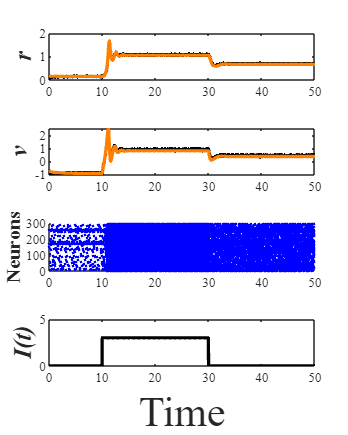

load('S_COBA.mat');
load('V_COBA.mat');
load('FRr_COBA.mat');
load('Vr_COBA.mat');
load('Raster_COBA.mat')

% Set default properties for the current script
set(0, 'DefaultAxesFontName', 'Times New Roman');
set(0, 'DefaultTextFontName', 'Times New Roman');

tvec = 0.001:0.001:50;

S_COBA = movmean(S_COBA,80);
V_COBA = movmean(V_COBA,50);

% Crear el subplot
figure('Units', 'inches', 'Position', [0, 0, 8, 10]);

% Primer subplot - Firing rates
subplot(4,1,1);
plot(tvec, S_COBA, 'color', 'black', 'LineWidth', 2)
hold on
plot(tvec, FRr_COBA, 'color', [1, 0.5, 0], 'LineWidth', 2)
ylabel('r', 'FontSize', 15, 'FontAngle', 'italic', 'FontWeight', 'bold')
hold off

% Segundo subplot - Voltage
subplot(4,1,2);
plot(tvec, V_COBA, 'color', 'black', 'LineWidth', 2)
hold on
plot(tvec, Vr_COBA, 'color', [1, 0.5, 0], 'LineWidth', 2)
ylabel('v', 'FontSize', 15, 'FontAngle', 'italic', 'FontWeight', 'bold')
hold off

% Tercer subplot - Spike Train
subplot(4,1,3);
Raster_COBA = ~Raster_COBA;
hold on;
for neuron = 1:size(Raster_COBA, 1)
    for time = 1:size(Raster_COBA, 2)
        if Raster_COBA(neuron, time) == 1
            plot(tvec(time), neuron, 'bo', 'MarkerSize', 1, 'MarkerFaceColor', 'b'); % 'k.' es para puntos negros
        end
    end
end
hold off;
ylabel('Neurons', 'FontSize', 12, 'FontWeight', 'bold');
xlim([0 max(tvec)]);
ylim([0 300]);

% Cuarto subplot - Applied Current
subplot(4,1,4);
Pulse = zeros(1,length(tvec));
Pulse(10/0.001:30/0.001) = 3;
plot(tvec, Pulse, 'color', 'black', 'LineWidth', 2)
xlabel('Time', 'FontSize', 25)
ylabel('I(t)', 'FontSize', 15, 'FontAngle', 'italic', 'FontWeight', 'bold')
ylim([0,5])

exportgraphics(gcf, 'COBASignals.png', 'Resolution', 300); % Guarda con mayor resolución